# Ophys Quick Start Example

Create a session filter object, using the `bot.sessionfilter` class. Since this is the first time we have used the toolbox, the manifest of all experimental data is downloaded from the Allen Brain Observatory.

bosf = bot.sessionfilter();

We can look at what targetted cortical structures are available to analyse, then filter the available sessions to select only the data from primary visual cortex (`'VISp'`).

bosf.targeted_structure

ans = 6×1 cell array
    {'VISal'}
    {'VISam'}
    {'VISl' }
    {'VISp' }
    {'VISpm'}
    {'VISrl'}



bosf.filter_sessions_by_targeted_structure('VISp')

ans =   sessionfilter with properties:

       valid_session_table: [1368×15 table]
    filtered_session_table: [432×15 table]
                  stimulus: {9×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: [15×1 double]
              container_id: [144×1 double]
                session_id: [432×1 double]
              session_type: {4×1 cell}
                  cre_line: {13×1 cell}
        eye_tracking_avail: [2×1 logical]


Only 138 experimental sessions are now available. We can filter further by whether or not eye tracking information is available, then by imaging depth and CRE line. 

bosf.filter_session_by_eye_tracking(true);
bosf.imaging_depth

ans =    175
   275
   285
   335
   350
   375



bosf.filter_sessions_by_imaging_depth(375);
bosf.cre_line

ans = 3×1 cell array
    {'Emx1-IRES-Cre' }
    {'Rbp4-Cre_KL100'}
    {'Sst-IRES-Cre'  }


bosf.filter_session_by_cre_line('Emx1-IRES-Cre')

ans =   sessionfilter with properties:

       valid_session_table: [1368×15 table]
    filtered_session_table: [1×15 table]
                  stimulus: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: 375
              container_id: 540168835
                session_id: 540168837
              session_type: {'three_session_C'}
                  cre_line: {'Emx1-IRES-Cre'}
        eye_tracking_avail: 1


Now only a single session remains after filtering. We can then use the `get_filtered_sessions()` method to obtain a `bot.session` object that encapsulates the data from this session.

bos = bosf.get_filtered_sessions();

This is a lightweight object; no experimental data has been downloaded, but we can examine some of the parameters of the session by accessing the object properties:

bos.sSessionInfo

ans = struct with fields:
        date_of_acquisition: '2016-08-22T20:17:30Z'
    experiment_container_id: 540168835
          fail_eye_tracking: 0
                         id: 540168837
              imaging_depth: 375
                       name: '20160822_261458_3StimC'
                specimen_id: 529204468
              stimulus_name: 'three_session_C'
          storage_directory: '/external/neuralcoding/prod12/specimen_529204468/ophys_experiment_540168837/'
      targeted_structure_id: 385
       experiment_container: [1×1 struct]
           well_known_files: [3×1 struct]
         targeted_structure: [1×1 struct]
                   specimen: [1×1 struct]
                   cre_line: 'Emx1-IRES-Cre'


Now let's extract the fluorescence traces from the cells imaged in this session. This causes the session data to be downloaded from the Allen Brain Observatory, which takes longer to complete:

[vtTimestamps, mfTraces] = bos.get_dff_traces();

whos mfTraces

  Name               Size                Bytes  Class     Attributes

  mfTraces      105956x184            77983616  single              



Now that we have the data for this session, let's plot a selecton of the traces:

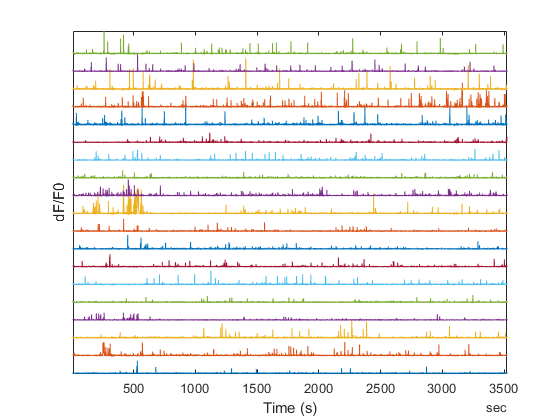

plot(vtTimestamps, bsxfun(@plus, mfTraces(:, 1:10:end), (0:10:size(mfTraces, 2))/3))

axis tight; xlabel('Time (s)'); set(gca, 'YTick', []); ylabel('dF/F0')

We can also extract behavioural data collected during the experiment:

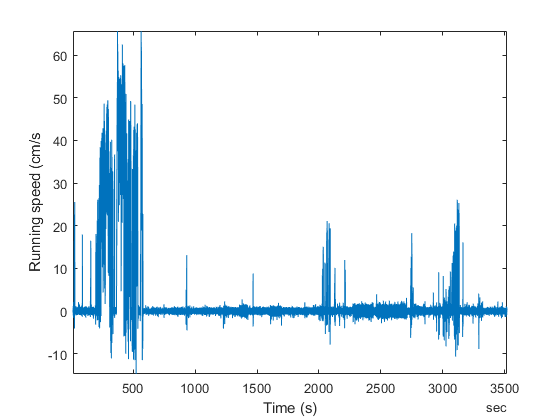

[vtTimestamps, vfRunningSpeed] = bos.get_running_speed();
plot(vtTimestamps, vfRunningSpeed);
axis tight; xlabel('Time (s)'), ylabel('Running speed (cm/s');

It's also important to know what stimuli were presented, and at what time:

bos.get_stimulus_epoch_table()

ans = 7×3 table
            stimulus            start_frame    end_frame
    ________________________    ___________    _________

    {'locally_sparse_noise'}         736         22458  
    {'spontaneous'         }       22608         31508  
    {'natural_movie_one'   }       31509         40567  
    {'locally_sparse_noise'}       41472         63194  
    {'natural_movie_two'   }       64099         73150  
    {'spontaneous'         }       73300         82199  
    {'locally_sparse_noise'}       82200        105730  


The methods `get_stimulus_table()` and `get_stimulus_template()` can then be used to obtain detailed frame-by-frame information about the stimuli that were presented. The method `get_stimulus()` acts as a look-up to return information about stimuli presented for a given fluorescence frame.